# Visualization

The purpose of this tutorial is to illustrate the underlying visualization methods used in the analysis of MR data. The tutorial includes examples of  tissue segmentation into gray matter and white matter, the definition of the surface boundary of the brain as a mesh, and related anatomical measurements, such as volume and surface area.

- Class:     Psych 204A

- Tutorial:  Visualization

- Authors:   Dougherty, Bowen, Wandell

- Date:      2010.10.21

- Duration:  45 minutes

- Copyright: Stanford University, RF Dougherty, R Bowen & BA Wandell

## Load a high-resolution T1-weighted MRI dataset of someone's head:

load mrTutVisualizationData.mat
whos

  Name                                  Size                       Bytes  Class                                    Attributes

  ADC                                   1x1                            8  double                                             
  AZ0                                   1x1                            8  double                                             
  AZ1                                   1x1                            8  double                                             
  B0                                    1x1                            8  double                                             
  BOLD3                                32x1                          256  double                                             
  D                                     1x16                         128  double                                             
  Dt                                    2x2                           32  double                                     

The variable anat contains the image data. We'll examine the brain mask and mesh later. The other array (voxDim) tells us the size of physical space (in millimeters) that each image voxel represents:

voxDim

voxDim =     0.9000    0.9000    0.9000



%%%%%%%%%%%%%%%%%%%%%%%%%%%
% ***** Question 1: ***** %
%%%%%%%%%%%%%%%%%%%%%%%%%%%
%
% a. What is the field of view of this image?
% b. What is the volume of one voxel?
%

## Examine a slice from this dataset

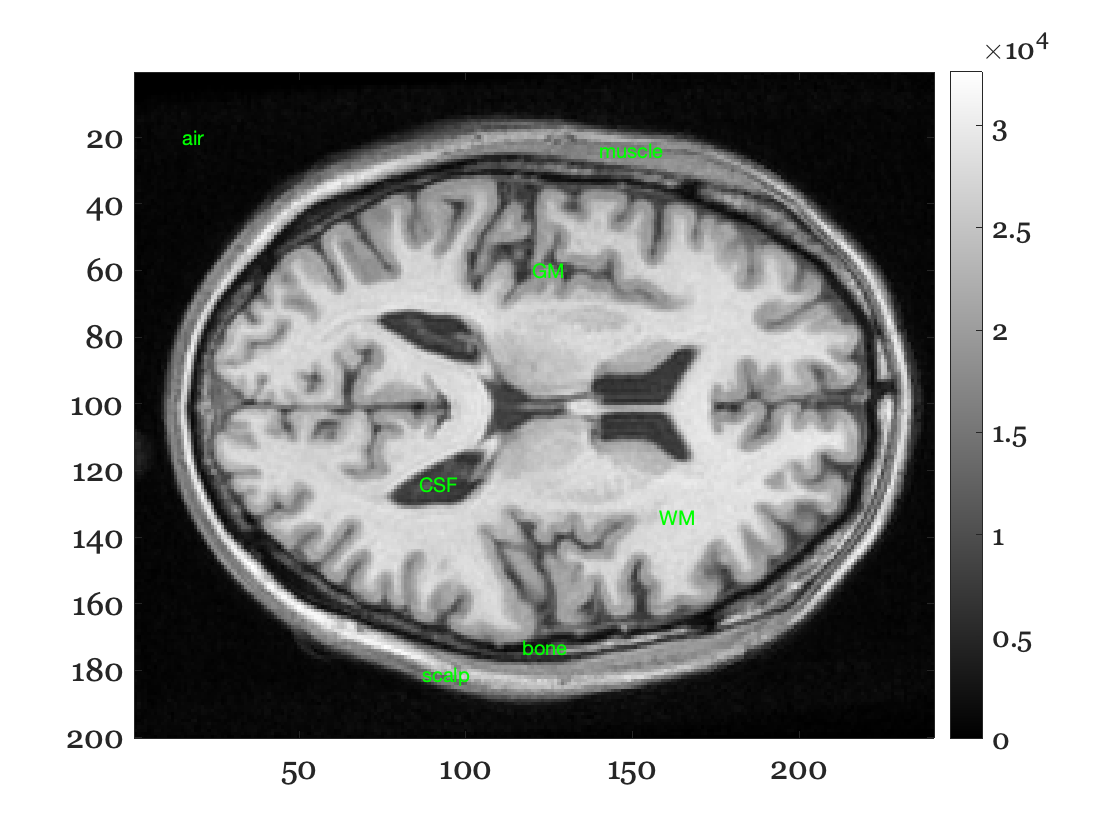

% The T1-weighted MR data are stored in a 3d array called 'anat'. Here's
% one slice from the middle of this array:
figure(1); set(gcf,'name','Middle slice');
imagesc(anat(:,:,90));

% We'll format the image to make it look nicer:
axis equal tight;
colormap gray;
colorbar;

% In this T1-weighted image, tissues with long T1 values show up as dark
% (cerebro-spinal fluid, CSF), medium T1 values are gray (gray matter, GM,
% and muscle), and shorter T1 values are white (white matter, WM,
% subcutaneous fat in the scalp). In addition to T1-weighting, this image
% includes some proton density weighting. That's why bone and air, which
% have relatively little free water, also show up as dark. Because this
% image is not based on a quantitative MR method, the image intensity
% values are in arbitrary units, so only the realtive intensities (image
% contrast) are important.

%%%%%%%%%%%%%%%%%%%%%%%%%%%
% ***** Question 2: ***** %
%%%%%%%%%%%%%%%%%%%%%%%%%%%
%
% Try to identify the different tissue types in the image.
% a. cerebro-spinal fluid (CSF)
% b. White matter (WM)
% c. Gray matter (GM)
% d. bone
% e. muscle
% f. scalp
% g. air
%

% Now let's add some labels so that you can see how well you did:
figure(1)
text(86,124,['\color{green}CSF']);
text(158,134,['\color{green}WM']);
text(120,60,['\color{green}GM']);
text(117,173,['\color{green}bone']);
text(140,24,['\color{green}muscle']);
text(87,181,['\color{green}scalp']);
text(15,20,['\color{green}air']);

## Working in three dimensions

Remember that this is a 3d dataset. Let's look at all the slices as a simple movie.

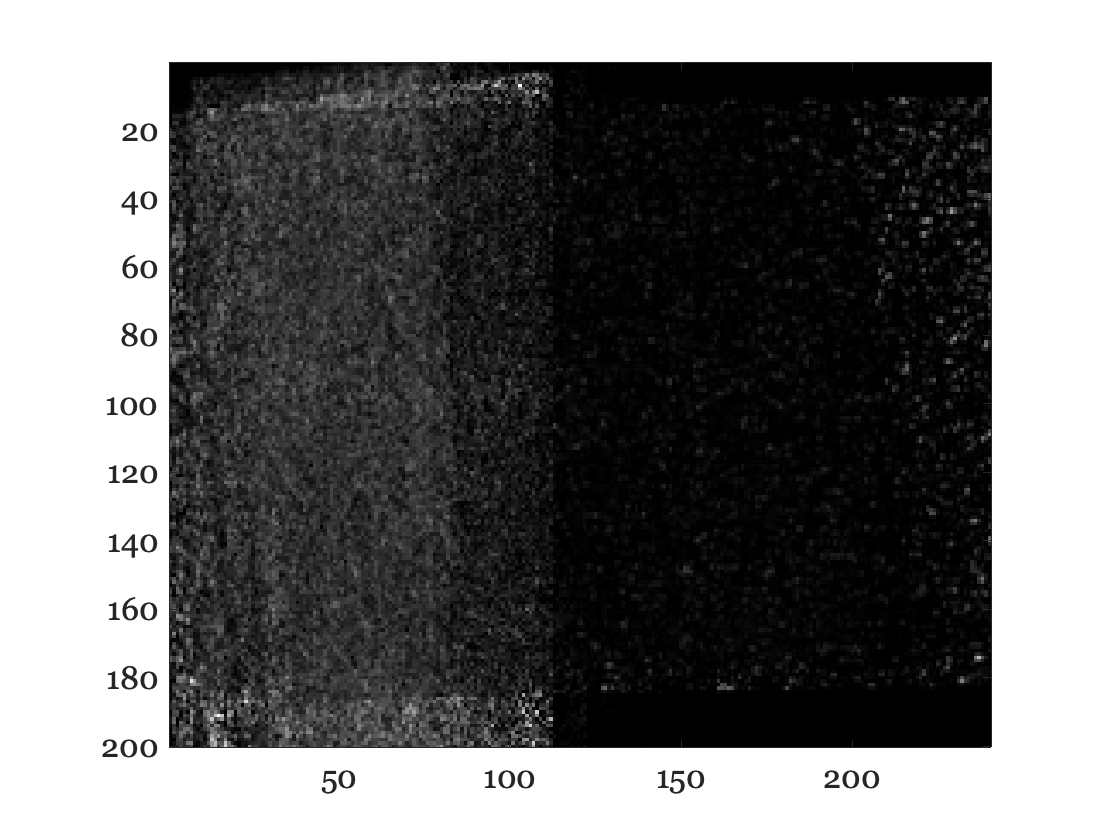

figure(2);
for(thisSlice=[1:size(anat,3)])
    imagesc(anat(:,:,thisSlice));
    axis equal tight;
    colormap gray;
    pause(0.05);
end


% We can also show the middle slice of each axis
figure(3);
middleSlices = round(size(anat)/2)

middleSlices =    100   120    90


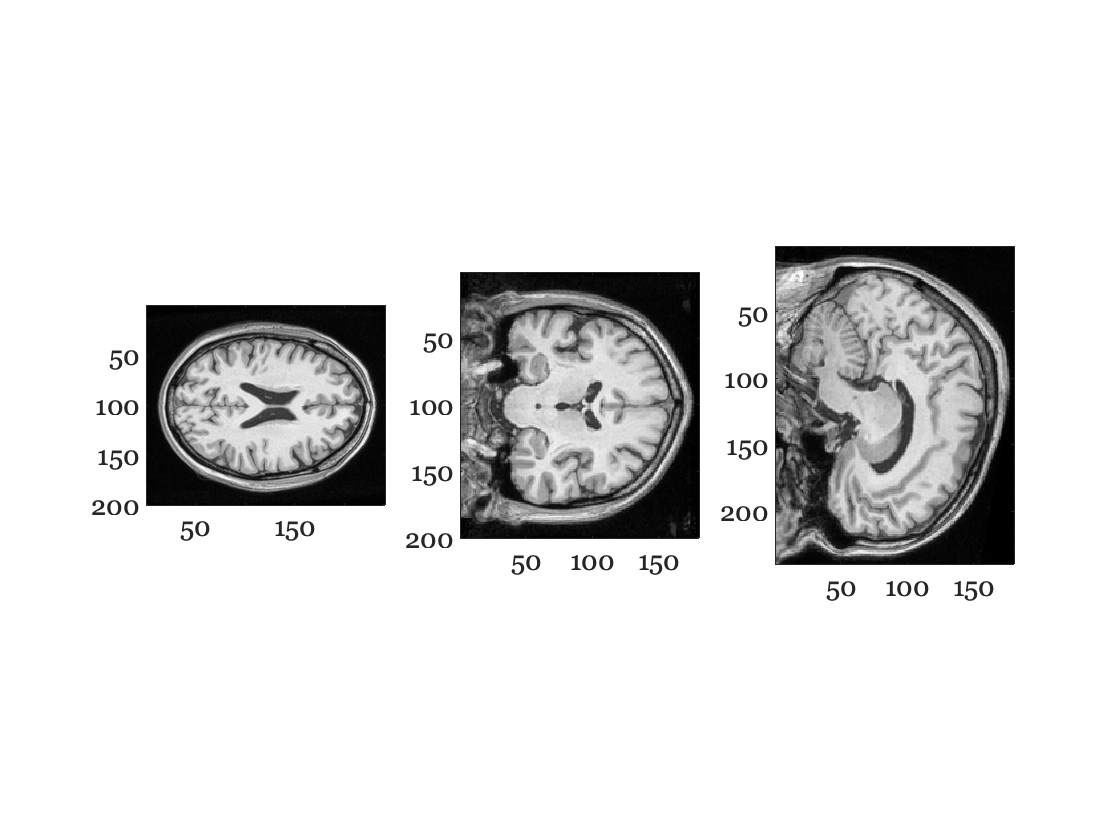

subplot(1,3,1);
imagesc(anat(:,:,middleSlices(1)));
axis equal tight; colormap gray;
subplot(1,3,2);
imagesc(squeeze(anat(:,middleSlices(2),:)));
axis equal tight; colormap gray; 
subplot(1,3,3);
imagesc(squeeze(anat(middleSlices(3),:,:)));
axis equal tight; colormap gray;

## Segment the brain tissue

The first step to segmenting the interesting brain tissues is to remove the annoying scalp and skull. This is often called "brain extraction." It can be done manually, by carfully labeling each voxel. There are also some very good algorithms that can do this task automatically. We've applied one of these tools (FSL BET: [http://www.fmrib.ox.ac.uk/fsl/bet2/](http://www.fmrib.ox.ac.uk/fsl/bet2/)) and saved the resulting brain mask. 

Here is the brain mask for the same middle slice that we saw above. This 'mask' is a simple image with 1's indicating brain tissue and 0's indicating non-brian tissue.

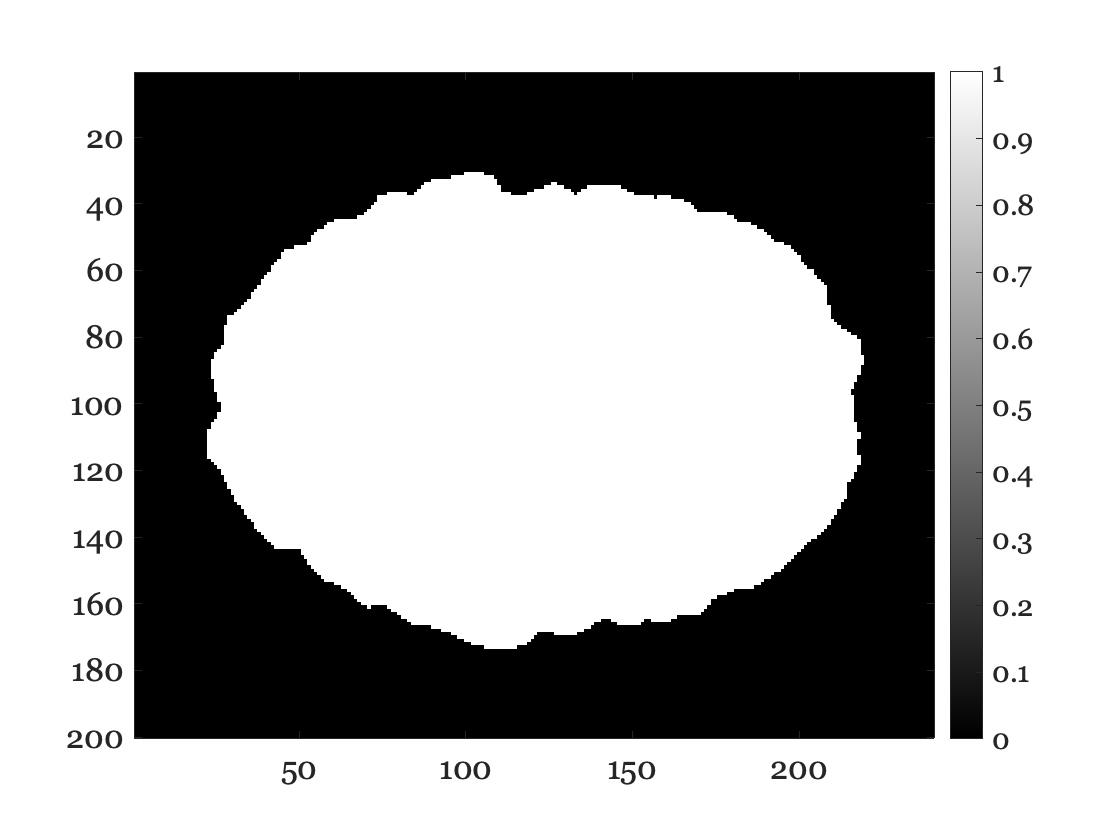

figure(4); set(gcf,'name','Brain mask for middle slice');
imagesc(brainMask(:,:,90));
axis equal tight; colormap gray; colorbar;

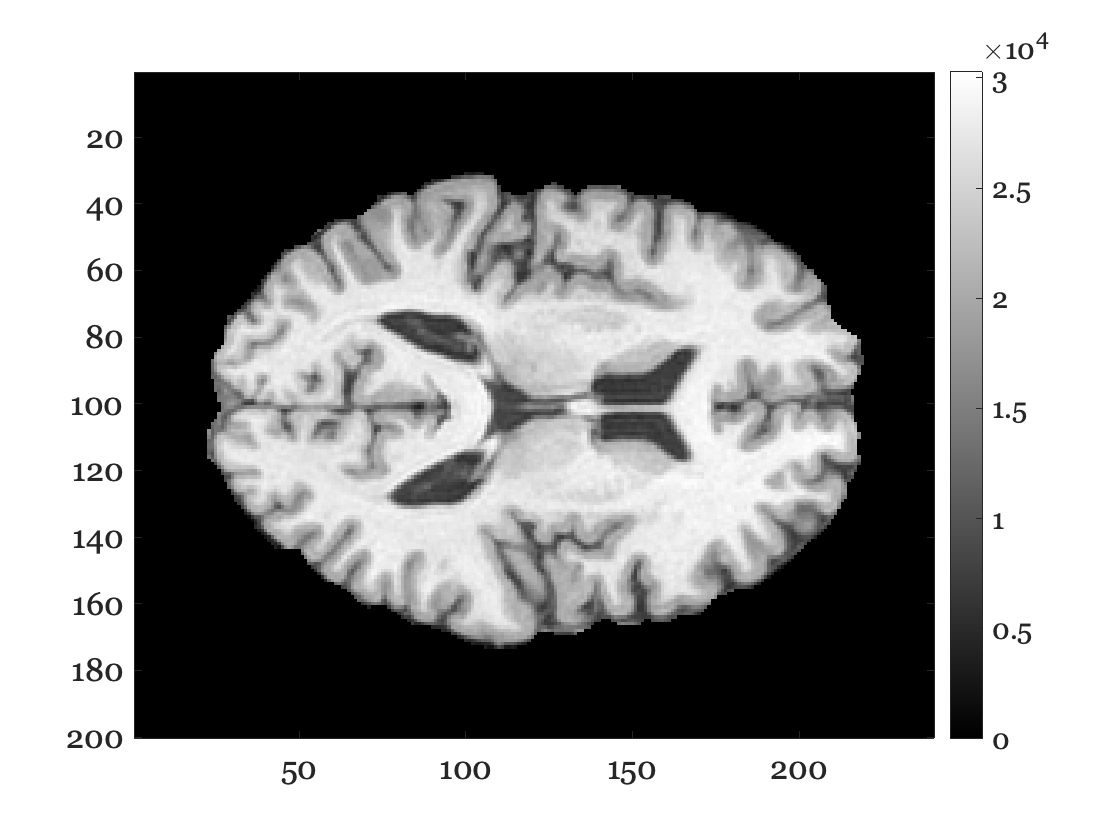


%%%%%%%%%%%%%%%%%%%%%%%%%%%
% ***** Question 3: ***** %
%%%%%%%%%%%%%%%%%%%%%%%%%%%
%
% What is the volume of the brain in cubic centimeters?
% Hint: the volume of one voxel in cubic mm is prod(voxDim).
%

% Now apply the brain mask by setting all non-brain voxels to 0:
brain = double(anat);
brain(~brainMask) = 0;
figure(5); set(gcf,'name','Brain only');
imagesc(brain(:,:,90));
axis equal tight; colormap gray; colorbar;

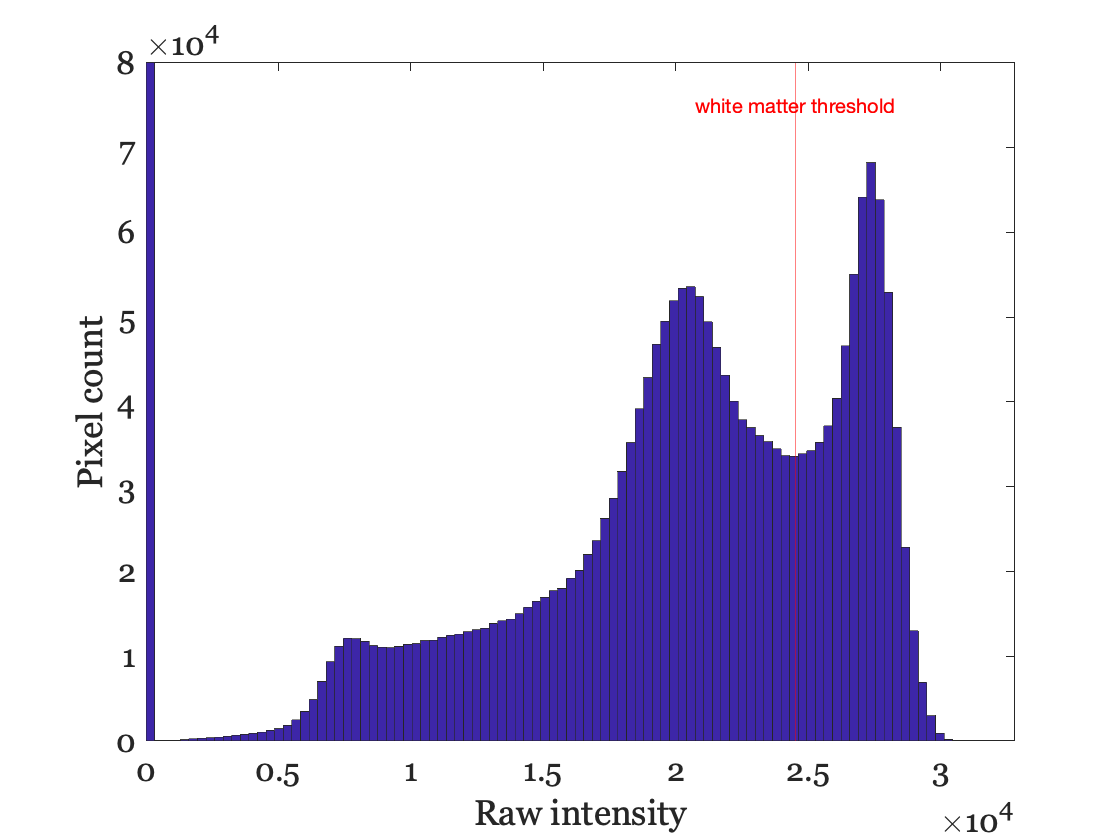


% Let's look at a histogram of the image intensities in the brain.
figure(6); set(gcf,'name','Image intensities in the brain');
hist(brain(:), 100);
xlabel('Raw intensity'); ylabel('Pixel count');
% There are many voxels with an intensity of zero, including all the stuff
% outside the brain that we set to zero above. Let's rescale the axes to
% make
% the more interesting features evident:
axis([0 32765 0 8e4]);

%%%%%%%%%%%%%%%%%%%%%%%%%%%
% ***** Question 4: ***** %
%%%%%%%%%%%%%%%%%%%%%%%%%%%
%
% a. How many peaks are there in this histogram?
% b. What tissue types do these peaks represent?
%

% Here's a line that is likely to divide white and gray matter intensities
wmThreshold = 24500;
figure(6)
line([wmThreshold wmThreshold], [0 8e4], 'color', 'r');
text(wmThreshold, 7.5e4, 'white matter threshold', 'color','r', 'HorizontalAlignment', 'center');

## Segment out the white matter based on this boundary

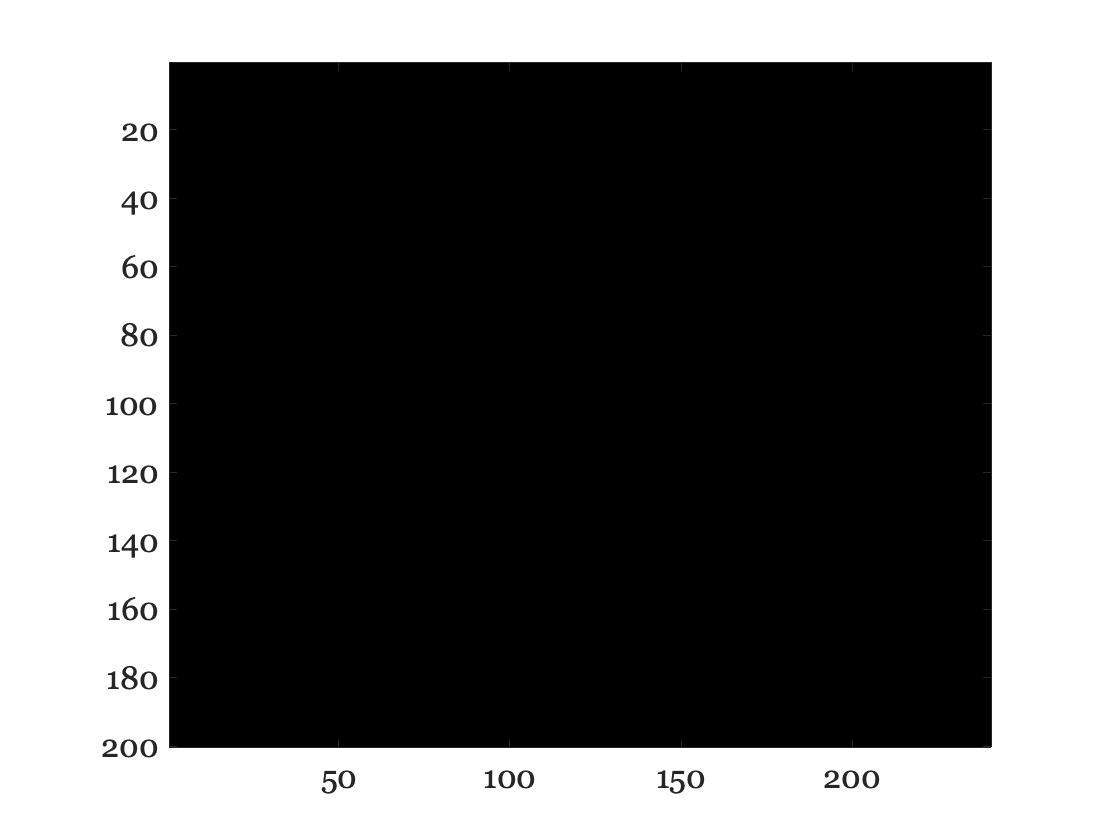

whiteMatter = brain > wmThreshold;
% Clean up the segmentation with a little smoothing. For a real
% segmentation, we would also want to have a human expert edit the
% segmentation to ensure that it is correct.
whiteMatter = smooth3(double(whiteMatter))>0.5;

% Inspect the segmentation
brainScaled = brain/max(brain(:));  % rescale intensities to be between 0 and 1
brainWmRgb = cat(4,brainScaled*.5+whiteMatter*.5,brainScaled,brainScaled);
figure(7); set(gcf,'name','White matter segmentation');
for(thisSlice=[1:size(brainWmRgb,3)])
    image(squeeze(brainWmRgb(:,:,thisSlice,:)));
    axis equal tight;
    pause(0.1);
end


%%%%%%%%%%%%%%%%%%%%%%%%%%%
% ***** Question 5: ***** %
%%%%%%%%%%%%%%%%%%%%%%%%%%%
%
% What is the volume of the white matter in cubic centimeters?
%

## View the brain surface.

The arachnoid is one of the three membranes that cover the brain (meninges). By fitting a surface to the brain mask, we get something that represents the arachnoid surface.

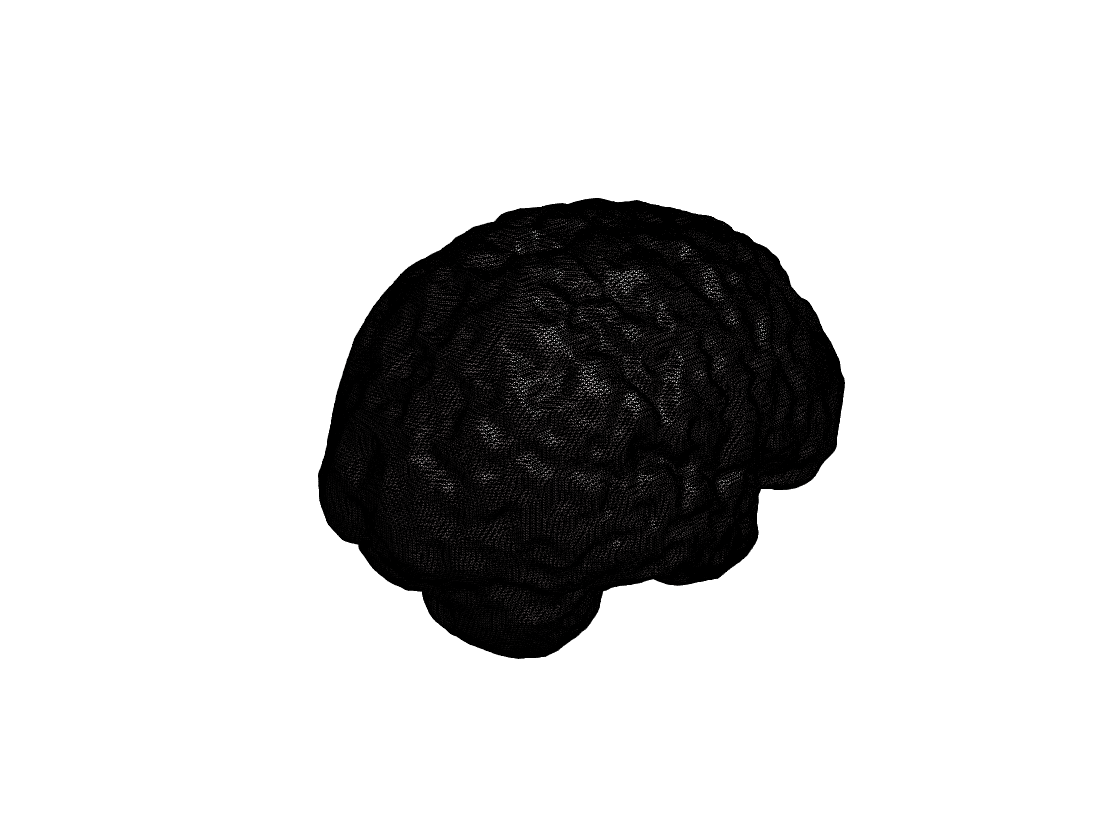

arachSmooth = smooth3(brainMask);
figure(8);
set(gcf, 'renderer', 'OpenGL');
% The following command might take a little while to complete.
p = patch( isosurface(arachSmooth) );
isonormals(arachSmooth, p);
set(p, 'FaceColor', [.5 .45 .46], 'EdgeColor','none');
daspect([1 1 1]);
view(3), axis vis3d tight off, camproj perspective, camlight, lighting phong
set(gcf,'Color','w');
rotate3d;

% Show the triangles that make up this mesh. (You'll probably need to zoom
% in to see them.)
set(p,'edgeColor','k');

## Measure the white matter surface.

We've used the isosurface function to fit a set of triangles to the white matter mask and saved them in the 'mesh' structure. This surface represents the boundary between cortical gray matter and white matter.

mesh

mesh = struct with fields:
    vertexNormals: [174240×3 double]
        curvature: [174240×1 double]
         vertices: [174240×3 double]
            faces: [349348×3 double]



% The triangles that make up this surface are represented as a list of
% vertices (points in 3d space) and a list of the triangles (faces). Each
% face is comprised of integers that are indices into the vertex list.
% For example, here are the three coordinates of the first triangle:
mesh.vertices(mesh.faces(1,:),:)

ans =     76    91    25
    75    91    26
    76    90    26


% These vertex coordinates are specified in the voxel coordinate space. To
% convert to physical space (ie. millimeters), we need to scale by the
% voxel dimentsions: 
verticesMm(:,1) = mesh.vertices(:,1)*voxDim(1);
verticesMm(:,2) = mesh.vertices(:,2)*voxDim(2);
verticesMm(:,3) = mesh.vertices(:,3)*voxDim(3);

% Now that the vertices are in real physical space, we can compute the area
% of the triangles using Heron's formula. First we compute the length of each
% of the three edges that comprise each triangle using the Euclidian distance 
% formula. We find the length of the first edge in the first triangle by 
% computing the distance between the two vertices that form that edge:  
v1 = verticesMm(mesh.faces(1,1),:)

v1 =    68.4000   81.9000   22.5000


v2 = verticesMm(mesh.faces(1,2),:)

v2 =    67.5000   81.9000   23.4000


firstEdgeDistance = sqrt( sum( (v1 - v2).^2 ) )

firstEdgeDistance = 1.2728


% We can compute all the edge lengths very quickly with this dense bit of
% code. The resulting arrays contain all three edge lengths for all the
% triangles, with the first edge in a, the second in b, and the third in c.
a = sqrt(sum((verticesMm(mesh.faces(:,1),:) - verticesMm(mesh.faces(:,2),:)).^2, 2));
b = sqrt(sum((verticesMm(mesh.faces(:,2),:) - verticesMm(mesh.faces(:,3),:)).^2, 2));
c = sqrt(sum((verticesMm(mesh.faces(:,3),:) - verticesMm(mesh.faces(:,1),:)).^2, 2));
% Let's check that we got the same answer as when we just did just one edge:
a(1)

ans = 1.2728

firstEdgeDistance

firstEdgeDistance = 1.2728


% Now find the half the perimeter of each triangle:
s = (a+b+c)/2;
% And finally, apply Heron's formula:
faceArea = sqrt(s.*(s-a).*(s-b).*(s-c));
% The total surface area, in mm^2 is:
sum(faceArea)

ans = 1.8868e+05

%%%%%%%%%%%%%%%%%%%%%%%%%%%
% ***** Question 6: ***** %
%%%%%%%%%%%%%%%%%%%%%%%%%%%
%
% a. What is the surface area of this person's white matter, in square centimeters?
% b. How many 8.5 x 11 inch sheets of paper would it take to cover this white matter surface?
%    (Hint: One inch equals 2.54 centimeters.)
% c. Assuming the cortex is 3mm thick, estimate the volume of the cortical gray matter and
%    compare this to the white matter volume.
%

## Visualize the 3d white matter surface.

First, we center the vertices on 0,0,0 so that all rotations are about the center of mass: 

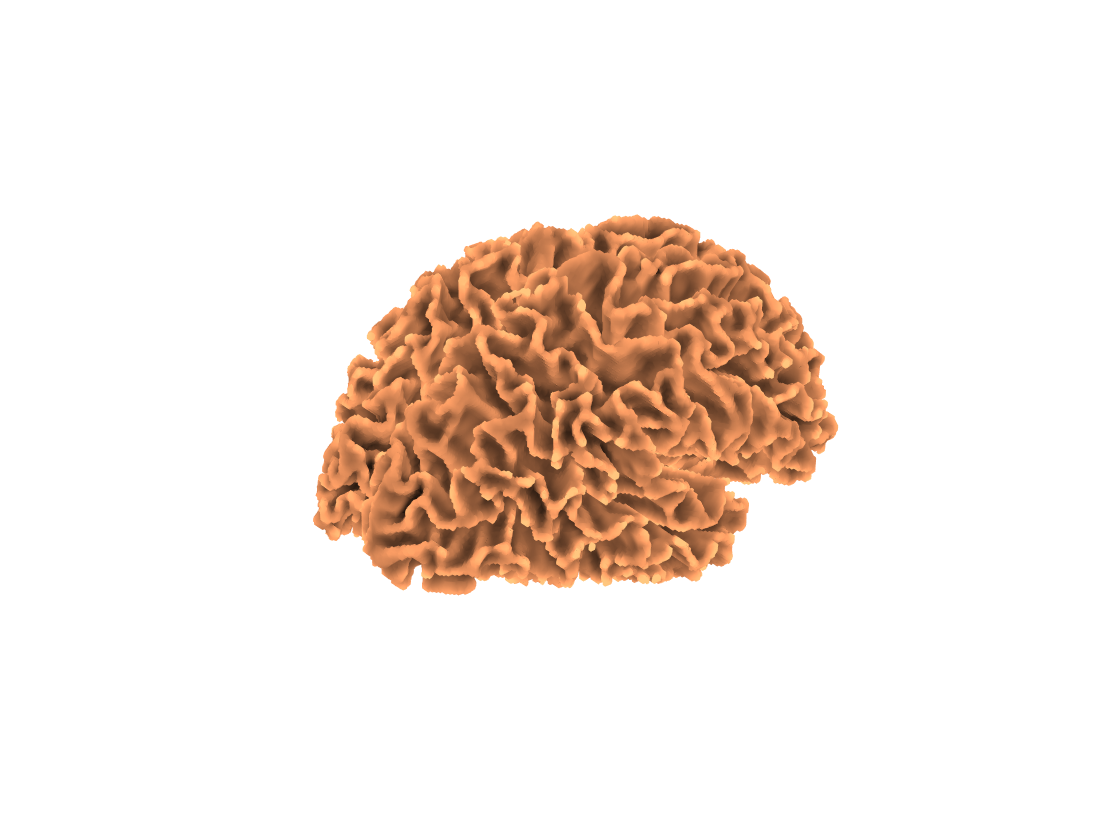

mesh.vertices(:,1) = mesh.vertices(:,1)-mean(mesh.vertices(:,1));
mesh.vertices(:,2) = mesh.vertices(:,2)-mean(mesh.vertices(:,2));
mesh.vertices(:,3) = mesh.vertices(:,3)-mean(mesh.vertices(:,3));
% Now make the figure:
figure(9);
set(gcf, 'renderer', 'OpenGL');
imagesc(0);
p = patch('vertices', mesh.vertices, 'faces', mesh.faces, ...
          'facecolor', 'interp',...
          'FaceVertexCData', mesh.curvature, ...
          'VertexNormals', mesh.vertexNormals, ...
          'edgecolor', 'none');
colormap(copper);      
daspect([1 1 1]);
view(3), axis vis3d tight off, camproj perspective
set(gcf,'Color','w');
rotate3d;

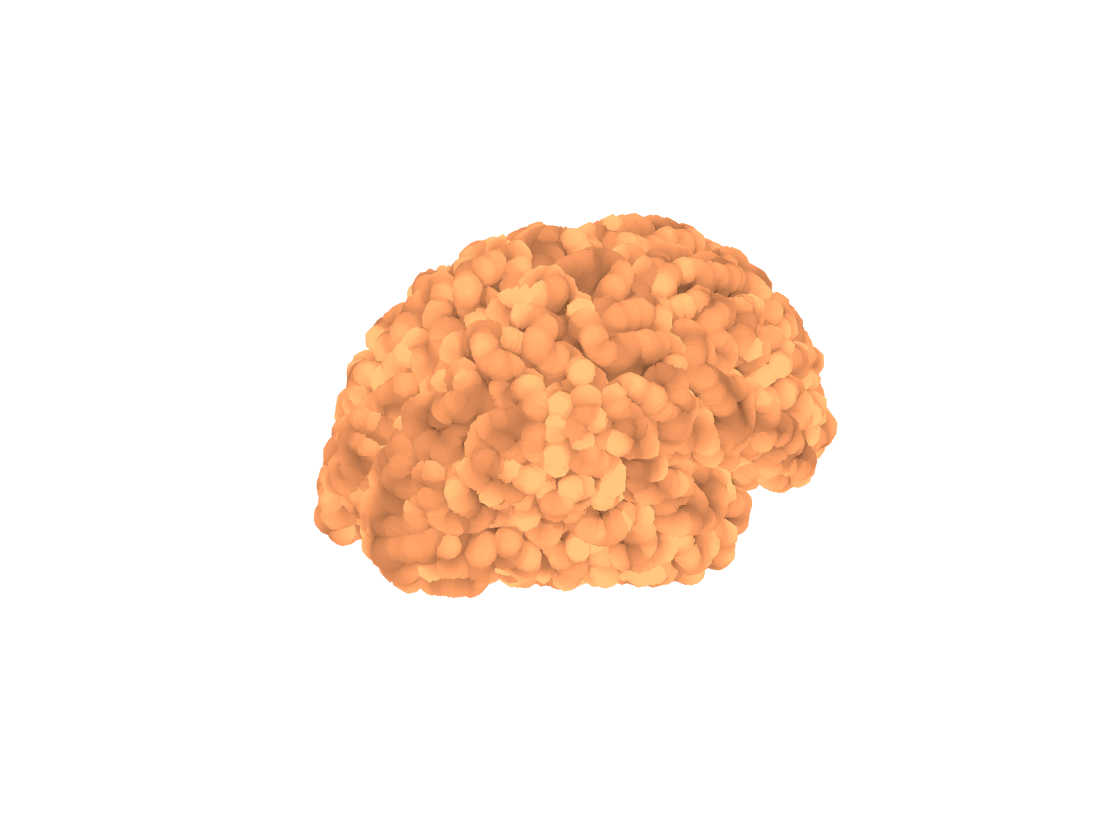


pialVertices = mesh.vertices;
for iter=1:4
    pialVertices = pialVertices+mesh.vertexNormals;
end

figure(10);
set(gcf, 'renderer', 'OpenGL');
imagesc(0);
p = patch('vertices', pialVertices, 'faces', mesh.faces, ...
          'facecolor', 'interp',...
          'FaceVertexCData', mesh.curvature, ...
          'VertexNormals', mesh.vertexNormals, ...
          'edgecolor', 'none');
colormap(copper);      
daspect([1 1 1]);
view(3), axis vis3d tight off, camproj perspective
set(gcf,'Color','w');
rotate3d;